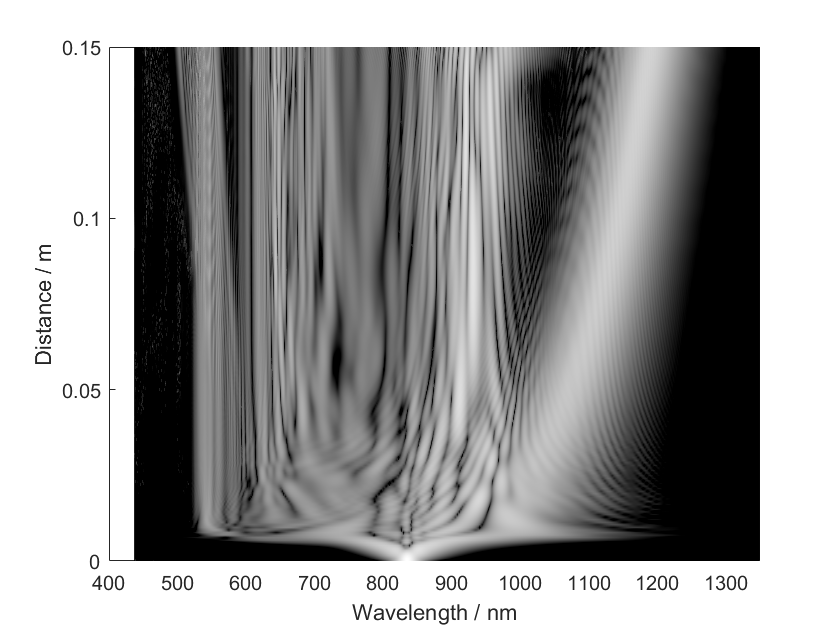

% Simulate supercontinuum generation for parameters similar to Fig.3 of Dudley et. al, RMP 78 1135 (2006)
% Written by J.C. Travers, M.H Frosz and J.M. Dudley (2009)
% Please cite this chapter in any publication using this code.
% Updates to this code are available at www.scgbook.info

n = 2^13;                             % number of grid points
twidth = 12.5;                        % width of time window [ps]
c = 299792458*1e9/1e12;               % speed of light [nm/ps]
wavelength = 835;                     % reference wavelength [nm]
w0 = (2.0*pi*c)/wavelength;           % reference frequency
T = linspace(-twidth/2, twidth/2, n); % time grid

% === input pulse
power = 10000;                         % peak power of input [W]
t0 = 0.0284;                           % duration of input [ps]
A = sqrt(power)*sech(T/t0);            % input field [W^(1/2)]

% === fibre parameters
flength = 0.15;                        % fibre length [m]
% betas = [beta2, beta3, ...] in units [ps^2/m, ps^3/m ...]
betas = [-11.830e-3, 8.1038e-5, -9.5205e-8, 2.0737e-10, ...
         -5.3943e-13, 1.3486e-15, -2.5495e-18, 3.0524e-21, ...
         -1.7140e-24];
gamma = 0.11;                          % nonlinear coefficient [1/W/m]
loss = 0;                              % loss [dB/m]

% === Raman response
fr = 0.18;                             % fractional Raman contribution
tau1 = 0.0122; tau2 = 0.032;           % Raman decay times [ps]
RT = (tau1^2 + tau2^2) / (tau1 * tau2^2) * exp(-T/tau2) .* sin(T/tau1); 
RT(T < 0) = 0;                         % heaviside step function
RT = RT / trapz(T, RT);                % normalise RT to unit integral

% === simulation parameters
nsaves = 200;                   % number of length steps to save field at

% === propagate field
[Z, AT, AW, W] = gnlse(T, A, w0, gamma, betas, loss, fr, RT, flength, nsaves);

% === plot output
lIW = 10*log10(abs(AW).^2); % log scale spectral intensity
mlIW = max(max(lIW)); % max value, for scaling plot
WL = 2*pi*c ./ W; 
iis = (WL > 400 & WL < 1350); % wavelength grid

% Plot spectral intensity as pseudocolor map
pcolor(WL(iis), Z, lIW(:, iis));
caxis([mlIW - 40.0, mlIW]); 
xlim([400, 1350]); 
shading interp;
xlabel('Wavelength / nm'); 
ylabel('Distance / m');
colormap gray

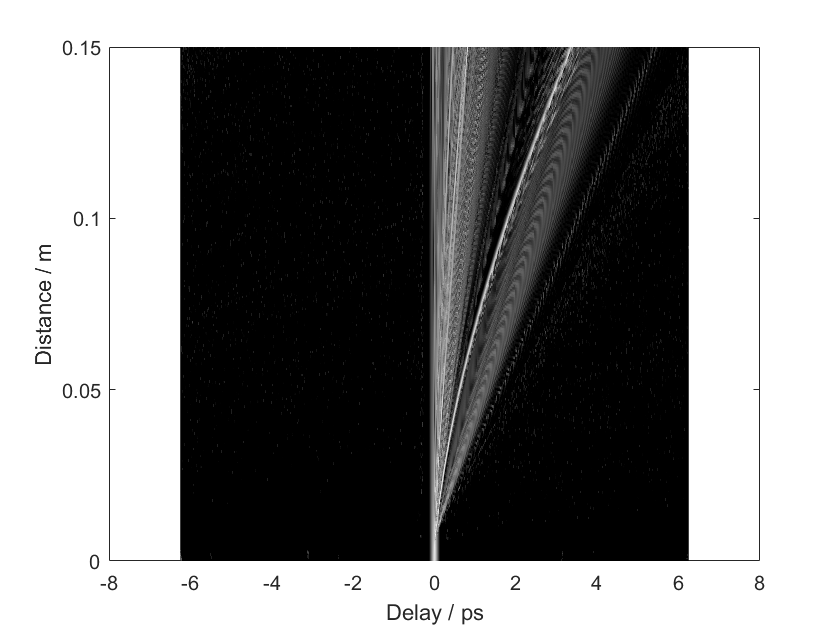


% Plot temporal intensity as pseudocolor map
lIT = 10*log10(abs(AT).^2); % log scale temporal intensity
mlIT = max(max(lIT)); % max value, for scaling plot
pcolor(T, Z, lIT); % plot as pseudocolor map
caxis([mlIT - 40.0, mlIT]); 
xlim([-0.5, 5]); 
shading interp;
xlabel('Delay / ps'); 
ylabel('Distance / m');
axis 'auto xy'

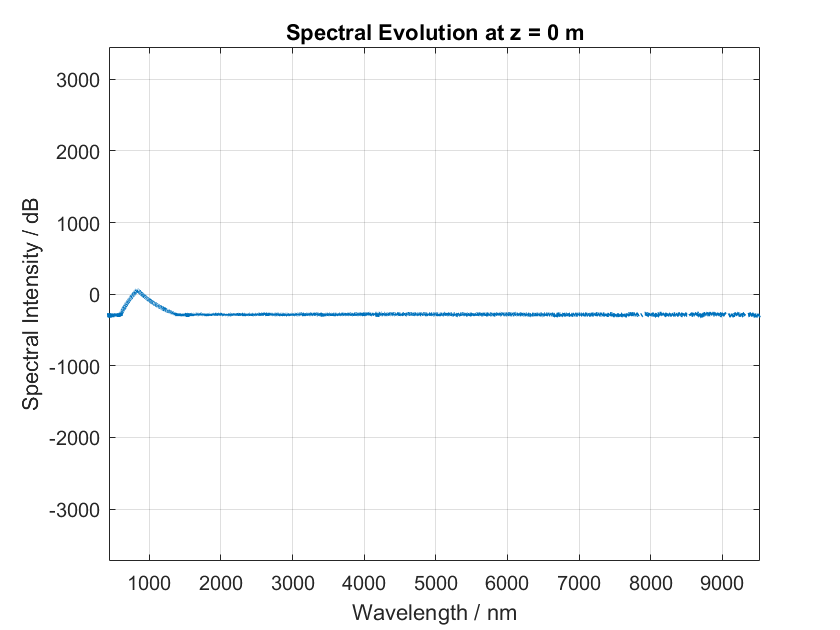


% Select a position in the fiber where to plot the spectral evolution
z_index = 1; % Select the middle point of Z
AW_z = AW(z_index, :); % Extract the spectral field at that position

% Calculate the spectral intensity at this position
lIW_z = 10*log10(abs(AW_z).^2); % log scale spectral intensity

% Calculate the corresponding wavelength grid
WL_z = 2*pi*c ./ W; % wavelength corresponding to the frequency grid

% Plot spectral intensity at a fixed Z (middle of the fiber length)
plot(WL_z, lIW_z, 'LineWidth', 2);
xlabel('Wavelength / nm');
ylabel('Spectral Intensity / dB');
title('Spectral Evolution at z = ' + string(Z(z_index)) + ' m');
axis equal
grid on;

function [Z, AT, AW, W] = gnlse(T, A, w0, gamma, betas, ...
    loss, fr, RT, flength, nsaves)
    % Propagate an optical field using the generalised NLSE
    
    n = length(T); dT = T(2)-T(1); % grid parameters
    V = 2*pi*(-n/2:n/2-1)'/(n*dT); % frequency grid
    alpha = log(10.^(loss/10)); % attenuation coefficient
    B = 0;
    for i = 1:length(betas) % Taylor expansion of betas
        B = B + betas(i)/factorial(i+1).*V.^(i+1);
    end
    L = 1i*B - alpha/2; % linear operator
    if abs(w0) > eps
        gamma = gamma/w0;
        W = V + w0;
    else
        W = 1;
    end
    
    RW = n*ifft(fftshift(RT.')); % frequency domain Raman
    L = fftshift(L); W = fftshift(W); % shift to fft space
    
    % Define RHS of Eq. (3.13)
    function R = rhs(z, AW)
        AT = fft(AW.*exp(L*z)); % time domain field
        IT = abs(AT).^2; % time domain intensity
        if (length(RT) == 1) || (abs(fr) < eps) % no Raman case
            M = ifft(AT.*IT); % response function
        else
            RS = dT*fr*fft(ifft(IT).*RW); % Raman convolution
            M = ifft(AT.*((1-fr).*IT + RS)); % response function
        end
        R = 1i*gamma*W.*M.*exp(-L*z); % full RHS
    end
    
    % Setup and run the ODE integrator
    Z = linspace(0, flength, nsaves); % select output z points
    options = odeset('RelTol', 1e-5, 'AbsTol', 1e-12, ...
        'NormControl', 'on'); % error control
    [Z, AW] = ode45(@rhs, Z, ifft(A), options); % run integrator
    
    % Process output of integrator
    AT = zeros(size(AW(1,:)));
    for i = 1:length(AW(:,1))
        AW(i,:) = AW(i,:).*exp(L.'*Z(i)); % change variables
        AT(i,:) = fft(AW(i,:)); % time domain output
        AW(i,:) = fftshift(AW(i,:))./dT; % scale
    end
    W = V + w0; % the absolute frequency grid
end
